%画像作成の下準備

data = readmatrix('/Users/daiki_daiku/Documents/研究/MATLABコード/アニメーション出力用データ.xlsx');
gage1 = 6.49763;%gageスタート
gage2 = 6.85575;%gageエンド

m = min(min(data(2:end,2:end)));%カラーバーの上限下限をそろえる
M = max(max(data(2:end,2:end)));

length = data(1,:);
s = find(length == gage1); %ゲージ部分の抜出
e = find(length == gage2);

[r c] = size(data(:,s:e));  %角度に変換しました
d = linspace(0,360,c);

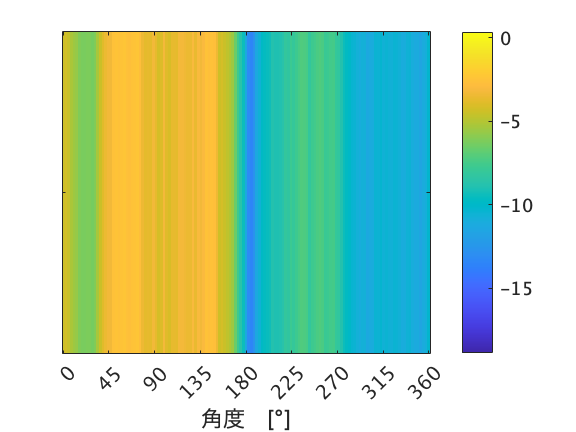

%画像1枚1枚をframesに格納

fig = figure; % Figure オブジェクトの生成
frames(r-1) = struct('cdata', [], 'colormap', []); % 各フレームの画像データを格納する配列らしい

for n = 2:r
   x = data(n,s:e);
   imagesc(d,0,x);
   colorbar;
   ax = gca;
   ax.XTick = [linspace(0,360,9)];
   ax.YTickLabel = cell(size(ax.YTickLabel)); %y軸の目盛りを消す
   xlabel("角度　[°]")
   caxis([m M]);
   drawnow; 
   frames(n-1) = getframe(fig); 
   
end

%拡張子を選択し出力

filename = 'test'; % ファイル名
type = "mp4";%出力形式を選択

switch type 
    case 'mp4' 
        filename = convertCharsToStrings(append(filename,'.mp4'));
        video = VideoWriter(filename, 'MPEG-4'); % ファイル名や出力形式などを設定
        open(video);
        writeVideo(video, frames); 
        close(video); 
    case 'gif'
        filename = convertCharsToStrings(append(filename,'.gif'));
        for i = 1:r-1
            [A, map] = rgb2ind(frame2im(frames(i)), 256); % 画像形式変換
            if i == 1
                imwrite(A, map, filename, 'gif', 'DelayTime', 1/30); % 出力形式(30FPS)を設定
            else
                imwrite(A, map, filename, 'gif', 'DelayTime', 1/30, 'WriteMode', 'append'); % 2フレーム目以降は"追記"の設定も必要
            end
        end
end
